# Cargar información de NDVI de la región Suroeste de Tamaulipas

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*
clear vars;
disp(">>> Declarando variables...ok")

>>> Declarando variables...ok


% umbral para ajuste de ventana y datos 
umbral_mapa=0.1;
umbral_datos = 0.8;
anio_inicio = 2000;
%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13Q1';
kml_file = "21-28-0010";  %%09/04/2021	09/05/2021

% Cargar los datos en los arreglos
m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1098 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1098 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


## Promedio

% ndvi_prom = f_mean_3dpp(arr_ndvi_mj);
% ndvi_prom(study_area==false)=nan;
% 
% figure;
% f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI",[0 1],"NDVI");
% f_draw_kml(dir_data,kml_file);

% umbral del indice
umbral_idc=2.0;

diaj=113; % 113	23	4	1	2021


anios=2000:2023;
meses = 1:12;
diasj = 1:16:366;

%diaj=97; % 6 abril
tmp = find( info_hdf.diaj == diaj );

serie_s = reshape( arr_ndvi_mj(round(ndvi_tam(1)/2),round(ndvi_tam(2)/2),tmp) ,[],1);
anomalies = f_anomaly_scan(serie_s,umbral_idc);

mas = numel(anomalies(anomalies==1))

mas =      0


igual = numel(anomalies(anomalies==0))

igual =     24


menos = numel(anomalies(anomalies==-1))

menos =      0


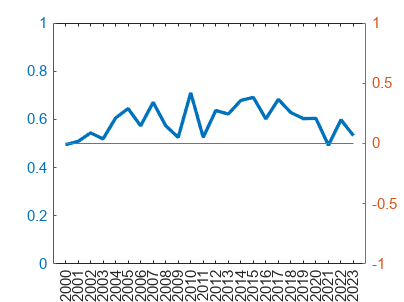



figure;
yyaxis left

plot(1:length(serie_s),serie_s,LineWidth=2);
ylim([0 1]);
xticklabels(anios);
xticks(1:1:24);
yyaxis right
plot(1:length(serie_s),anomalies);
ylim([-1 1]);

%[anomaly,value]=f_anomaly_scan(test_t,serie_s);


## Analisis con anomaly_scan

arr_anomalias =zeros(ndvi_tam(1),ndvi_tam(2),num_registros_totales);
mapa_anomalias =zeros(ndvi_tam(1),ndvi_tam(2));

bp=waitbar(0,'Procesando el TSA'); 
for d = diasj
    for i=1:ndvi_tam(1)
        for j=1:ndvi_tam(2)
            if ~isnan(study_area(i,j))
                tmp = find(  info_hdf.diaj == d );
                serie_s = reshape( arr_ndvi_mj(i,j,tmp) ,[],1);
                anomalias = f_anomaly_scan(serie_s,umbral_idc);
                arr_anomalias(i,j,tmp) = anomalias;
            end
        end
    end
    waitbar(d/365,bp,sprintf('Procesando el TSA (%3.0f%%) ',(d/365*100)));
end
close (bp);

% dias incendio 
%fecha 09/04/2021	09/05/2021
% idx  487 (7/4)  488(23/4)  489 (9/5)
%diaj  97          113        129
%idx = 489

% for idx=490:492
%     mapa_anomalias(:,:) = arr_anomalias(:,:,idx);
%     
%     figure;
%     mapa_anomalias(study_area==false)=nan;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_anomalias,flipud(m_colmap('diverging',256)),[-1 1],"TSA");
%     f_draw_kml(dir_data,kml_file);
%     exportgraphics(gca,"img/00idc_idc_"+umbral_idc+"idx_"+idx+".png",'Resolution',300);
%     
%     ndvi_map = arr_ndvi_mj(:,:,idx);
%     ndvi_map(study_area==false)=nan;
%     
%     figure;
%     mapa_anomalias(study_area==false)=nan;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_map,"NDVI",[0 1],"NDVI");
%     f_draw_kml(dir_data,kml_file);
%     exportgraphics(gca,"img/00ndvi_idc_"+umbral_idc+"idx_"+idx+".png",'Resolution',300);
% 
% end


## Resultados espaciales por día

tbl_prueba_umbral = zeros(num_registros_totales,3);
bp=waitbar(0,'Procesando resultados del TSA'); 
for i = 1:num_registros_totales
%     for i=1:ndvi_tam(1)
%         for j=1:ndvi_tam(2)
%             if ~isnan(study_area(i,j))
%                 tmp = find(  info_hdf.diaj == d );
%                 serie_s = reshape( arr_ndvi_mj(i,j,tmp) ,[],1);
%                 anomalias = f_anomaly_scan(serie_s,umbral_idc);
%                 arr_anomalias(i,j,tmp) = anomalias;
%             end
%         end
%     end
    mapa_anomalias(:,:) = arr_anomalias(:,:,i);
    mas = numel(mapa_anomalias(mapa_anomalias==1));
    igual = numel(mapa_anomalias(mapa_anomalias==0));
    menos = numel(mapa_anomalias(mapa_anomalias==-1));
    
    tbl_prueba_umbral(i,:) = [mas; igual; menos];
    waitbar(i/num_registros_totales,bp,sprintf('Procesando resultados del TSA (%3.0f%%) ',(i/num_registros_totales*100)));
end
close (bp);

## Analisis completo

% % % Arreglo donde se almacenara el promedio de NDVI por año
% % mapa_anomalias =zeros(ndvi_tam(1),ndvi_tam(2));
% % %idx = 493;
% % tbl_prueba_umbral = zeros(num_registros_totales,3);
% % 
% % bp=waitbar(0,'Procesando el IDC'); 
% % 
% % for h=1:num_registros_totales
% % 
% %    diaj =  info_hdf(h,"diaj").diaj; %% 97;
% %  
% %     for i=1:ndvi_tam(1)
% %         for j=1:ndvi_tam(2)
% %             if ~isnan(study_area(i,j))
% %                 tmp = find(  info_hdf.diaj == diaj );
% %                 serie_s = reshape( arr_ndvi_mj(i,j,tmp) ,[],1);
% %                 anomalia = f_anomaly(arr_ndvi_mj(i,j,h),serie_s,umbral_idc);
% %                 mapa_anomalias(i,j)=anomalia;
% %             end
% %         end
% %     end
% %     
% %     % figure;
% %     % mapa_anomalias(study_area==false)=nan;
% %     % f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_anomalias,flipud(m_colmap('diverging',256)),[-1 1],"Cambios");
% %     % f_draw_kml(dir_data,kml_file);
% %     
% %     mas = numel(mapa_anomalias(mapa_anomalias==1));
% %     igual = numel(mapa_anomalias(mapa_anomalias==0));
% %     menos = numel(mapa_anomalias(mapa_anomalias==-1));
% %     
% %     tbl_prueba_umbral(h,:) = [mas; igual; menos];
% %     waitbar(h/num_registros_totales,bp,sprintf('Procesando el IDC (%3.0f%%) ',(h/num_registros_totales*100)));
% % 
% % end
% % % disp("Aumento: "+(mas/total_pixels)*100);
% % % disp("Igual: "+(igual/total_pixels)*100);
% % % disp("Disminución: "+(menos/total_pixels)*100);
% % close (bp);

%generar las etiquetas de año y estación

lbl_meses = ["Ene","Febrero","Marzo","Abril","Mayo","Junio","Julio","Agosto","Septiembre","Octubre","Noviembre","Diciembre"];
lbl_ejex_meses = string(1: length(anios));

a=1;
for i=anios
    for j=meses
        if j==1
            fecha =  strcat( lbl_meses(j)," ",""+i);
            lbl_ejex_meses (a) =fecha;
        end
      
    end
    a=a+1;
end
lbl_ejex_meses(1) = "Feb 2000";

t_ejey = 0:1000:20000;
lbl_ejey = string(t_ejey);

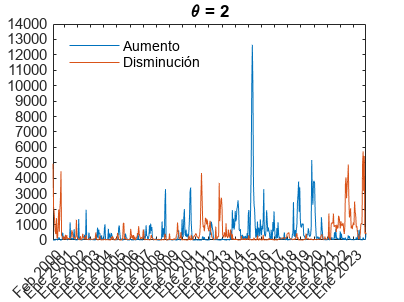



figure;
plot(tbl_prueba_umbral(:,[1 3]));
xticklabels(lbl_ejex_meses);
xticks([1 21:23:num_registros-21]);
xtickangle(45);
%ylim([0 1]);
xlim([1 num_registros]);

yticks(t_ejey);
yticklabels(lbl_ejey);

legend({'Aumento','Disminución'},'Location','northwest');
legend('boxoff');
title("\theta = "+umbral_idc);
promedio = mean(tbl_prueba_umbral);
desv=std(tbl_prueba_umbral);

exportgraphics(gca,"img/00_idc_"+umbral_idc+"_historico.png",'Resolution',300);


% % 
% % figure;
% % plot(tbl_prueba_umbral(21:end,[1 3]));
% % xticklabels(lbl_ejex_meses);
% % xticks( 1:23:num_registros-21);
% % xtickangle(45);
% % %ylim([0 1]);
% % xlim([1 num_registros-21]);
% % legend({'Aumento','Disminución'},'Location','northwest')
% % legend('boxoff')
% % 
% % promedio = mean(tbl_prueba_umbral)
% % desv=std(tbl_prueba_umbral)